# A minimum jerk trajectory

This m-function is the trajectory generator with a minimum jerk for vehicle lane-switching. The trajectory, along with the vehicle's other physical state,i.e., speed and acceleration should be calculated and output for vehicle control.

## Jerk

Smoothness can be quantified as a function of a jerk, which is the third time derivative of location. If the location of a vehicle is specified by variable $x(t)$, then the jerk is:


$$\dddot x(t)=\frac{d^3x(t)}{dt^3}$$


For comfort consideration, the sum of the squared jerk along the vehicle's trajectory should be minimized. The jerk cost is measured by:


$$H(x(t))=\frac{1}{2}\int _{t_i} ^{t_f} \dddot x(t)^2dt
$$


where $t_i
$ and $t_f$ are start and end time of the trajectory. The $\frac{1}{2}$ factor in the front makes the calculation come out prettier; otherwise, it has no special significance).

We assume that the vehicle remains the same velocity at the beginning and end of the trajectory, which means $\ddot x(t_i)=\ddot x(t_f)=0$

## Calculus of the variations.

The technique calculus of the variation resembles finding the minimum of the function. The variation is a function we can name $\eta(t)$. The variation has the special property that it smoothly goes away at the boundary conditions, i.e., at the beginning and end of the trajectory:


$$\eta(t_i)=\eta(t_f)=0
\\ \dot \eta(t_i)=\dot \eta(t_f)=0
\\ \ddot \eta(t_i)=\ddot \eta(t_f)=0$$


To minimize $H(x(t))$,we first replace $x(t)$by a variation $x(t) \mapsto x(t)+e\eta(t)$:


$$H(x+e\eta)=\frac{1}{2}\int^{t_f}_{t_i}(\dddot x +e\dddot\eta)^2dt
\\ \frac{dH(x+e\eta)}{e}=\int^{t_f}_{t_i}(\dddot x +e\dddot\eta)\dddot \eta dt
\\ \frac{dH(x+e\eta)}{e} \big| _{e=0} =\int^{t_f}_{t_i}\dddot x \ \dddot\eta dt
$$


Using integration by parts, we can rewrite this integral as:


$$\int ^{t_f}_{t_i}\dddot x \dddot \eta dt=  \dddot x \dddot \eta \big| ^{t_f}_{t_i} -\int^{t_f}_{t_i} \ddot \eta x^{(4)}dt=-\int ^{t_f}_{t_i} \ddot \eta x^{(4)}dt$$


Continuing the integration by parts:


$$\int ^{t_f}_{t_i} x^{(5)} \dot \eta dt=   x^{(5)} \eta \big| ^{t_f}_{t_i} -\int ^{t_f}_{t_i}  \eta x^{(6)}dt=-\int ^{t_f}_{t_i}  \eta x^{(6)}dt$$


The final integral:


$$\frac{dH(x+e\eta)}{e} \big |_{e=0}=-\int^{t_f}_{t_i}\eta x^{(6)}dt =0$$


The above property must hold true for any function $\eta(t)$, and therefore we have the fact that $x^{(6)}=0$, which means that function $x(t)$should have its sixth derivative equal to zero to have a minimum jerk function. $x(t)$has the general form of:


$$x(t)=a_0+a_1t+a_2t^2+a_3t^3+a_4t^4+a_5t^5$$


with derivatives:


$$\dot x(t)=a_1+2a_2t+3a_3t^2+4a_4t^3+5a_5t^4
\\ \ddot x(t)=2a_2+6a_3t+12a_4t^2+20a_5t^3$$


## Implementation in Matlab

To find the constants of the function $x(t)$, boundary values are required as inputs of the m function:

frequency = 10;%Number of commands per sec
current_point=[10 10];%current_point is a 1x2 array that represents vehicle's location at the
%beginning of the lane-switching trajectory
t=3;% the time required for the whole trajectory
v_x=20;%the vehicle's x-direction speed at the beginning of the lane-switching
lane_width=5;%the distance between adjacent lane centerline 

%temperory variables for better understanding
x_i=current_point(1,1);
y_i=current_point(1,2);
x_f=t*v_x+x_i;
y_f=y_i+lane_width;

To calculate the 2-D trajectory, we use x and y to denote distance in longitudinal and lateral direction to vehicle framework:

We assume that the vehicle remains its velocity in x direction, thus we have:

x=[];
x_dot=[];
x_ddot=[];
for i=0:1/frequency:t
x=[x,i*v_x+x_i];
x_dot=[x_dot,v_x];
x_ddot=[x_ddot,0];
end
state_x=[x;x_dot;x_ddot];


$$y(t_i=0)=y_i \rightarrow a_0=y_i
\\ \dot y(t_i=0)=0 \rightarrow a_1=0
\\ \ddot y(t_i=0)=0 \rightarrow a_2=0;$$



$$y(t_f=t)=y_f \rightarrow a_3t^3+a_4t^4+a_5t^5=y_f
\\ \dot y(t_f=t)=0 \rightarrow 3a_3t^2+4a_4t^3+5a_5t^4=0
\\ \ddot y(t_f=0)=0 \rightarrow 6a_3t+12a_4t^2+20a_5t^3=0;$$


$a_3,a_4 $ and $a_5$ can be acquired by solving the equations above:

a0=y_i;
a1=0;
a2=0;
syms a3 a4 a5;
[a3,a4,a5]=solve([a0+a3*t^3+a4*t^4+a5*t^5==y_f,
3*a3*t^2+4*a4*t^3+5*a5*t^4==0,
6*a3*t+12*a4*t^2+20*a5*t^3==0,],[a3,a4,a5]);
a3=double(a3);
a4=double(a4);
a5=double(a5);

Thus the function of the most smoothly trajectory in y direction is arrived:

y=[];
y_dot=[];
y_ddot=[];
for i=0:1/frequency:t
y=[y,a0+a1*i+a2*i^2+a3*i^3+a4*i^4+a5*i^5];
y_dot=[y_dot,a1+2*a2*i+3*a3*i^2+4*a4*i^3+5*a5*i^4];
y_ddot=[y_ddot,2*a2+6*a3*i+12*a4*i^2+20*a5*i^3];
end
state_y=[y;y_dot;y_ddot];

Corresponding yaw angle is the arc tangent function of $v_y/v_x$

yaw_angle=[];
for i=2:length(x_dot)
    yaw_angle(i)=atan(y_dot(i)/ (x_dot(i)));
end

We can then visualize the trajectory by using plot function:

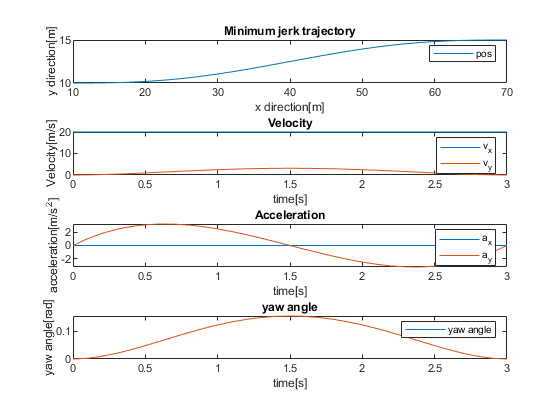

figure
i=0:1/frequency:t;
subplot(4,1,1);
plot(state_x(1,:),state_y(1,:));
% pbaspect([2 1 1]);
legend('pos');
title("Minimum jerk trajectory");
xlabel("x direction[m]");
ylabel("y direction[m]");
subplot(4,1,2);
plot(i,state_x(2,:))
hold on;
plot(i, state_y(2,:));
legend('v_x','v_y');
title("Velocity");
xlabel("time[s]");
ylabel("Velocity[m/s]");
subplot(4,1,3);
plot(i, state_x(3,:));
hold on;
plot(i, state_y(3,:));
legend('a_x','a_y');
title("Acceleration");
xlabel("time[s]");
ylabel("acceleration[m/s^2]");
subplot(4,1,4);
plot(i, yaw_angle);
hold on;
plot(i, yaw_angle);
legend('yaw angle');
title("yaw angle");
xlabel("time[s]");
ylabel("yaw angle[rad]");

## Reference

Kyriakopoulos, K. J., & Saridis, G. N. (1991). Minimum jerk trajectory planning for robotic manipulators. *Cooperative Intelligent Robotics in Space*, *1387*, 159. https://doi.org/10.1117/12.25421